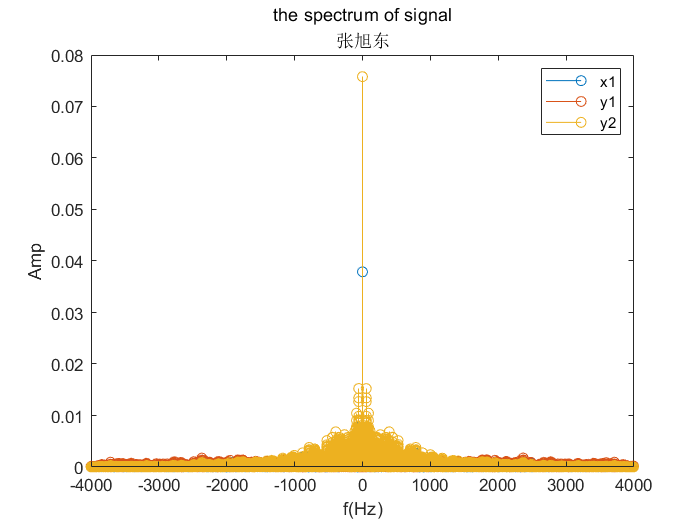

[x1,fs1]=audioread('D:\Study in SUSTech\First semester of junior year\Digital Signal Processing\lab\lab2\lab2\Lab2\music.au');
sound(x1);
y1=difference1(x1);
sound(y1);
y2=difference2(x1);
sound(y2);

amplitude1 = abs(fftshift(fft(x1, length(x1))))/length(x1);    % 计算幅度谱，fftshift是为了交换正负频率谱，fft后紧接着要除信号长度
f1 = (0:length(x1)-1)/length(x1)*fs1 - fs1  /2 ; % 计算频率轴，减Fs/2是为了正确显示0频位置
amplitude2 = abs(fftshift(fft(y1, length(y1))))/length(y1);    % 计算幅度谱，fftshift是为了交换正负频率谱，fft后紧接着要除信号长度
f2 = (0:length(y1)-1)/length(y1)*fs1 - fs1  /2 ; % 计算频率轴，减Fs/2是为了正确显示0频位置
amplitude3 = abs(fftshift(fft(y2, length(y2))))/length(y2);    % 计算幅度谱，fftshift是为了交换正负频率谱，fft后紧接着要除信号长度
f3 = (0:length(y2)-1)/length(y2)*fs1 - fs1  /2 ; % 计算频率轴，减Fs/2是为了正确显示0频位置
stem(f1, amplitude1);hold on;
stem(f2, amplitude2);hold on;
stem(f3, amplitude3);hold on;
xlabel('f(Hz)')
ylabel('Amp')
title(['the spectrum of signal' newline '张旭东']);
legend('x1','y1','y2');